# Clasificador de dos clases

Ahora que tenemos las imágenes cortadas, entonces podemos pocreder a usarlas. Sin embargo, antes de eso debemos de separar las imágenes en 3 conjuntos: entrenamiento, validación y prueba. Sabemos lo siguiente gracias a los nombre de las imágenes:

- Tenemos 300 imágenes con Cloudy

- Tenemos 357 imágenes con Sunrise

Usaremos las primeras **190 imágenes de cada categoría** para conformar el dataset de entrenamiento, mientras que para el conjunto de validación usaremos **15 de cada categoría** y **el resto** será de prueba. Se renombraron las imágenes y se pusieron en carpetas con un nombre respectivo al del dataset al que pertenece. Con lo que para prueba nos quedan:

- 95 imágenes para Cloudy

- 152 imágenes para Sunrise

## Entrenamiento

En esta sección ponemos la conifguración inicial. Primero seleccionemos alfa, recordemos que es la tasa de aprendizaje de la red. Un valor **más pequeño** significa que tardará más épocas en dar pesos W y bias B, se sacrifica tiempo a cambio de precisión. Por el contrario, un alfa mayor dará saltos más grandes, lo cual puede ser mucho más rápido, pero con una respuesta muy imprecisa.

alfa = 0.17;

Configuremos las capas de la red, utilizaremos function handlers (se escriben como @función), las capas tienen sus respectivas derivadas en el cell de derivadas. Mientras que neuronas simboliza el número de nueronas por capas. Aquí dsig simboliza la derivada de sigmoid con un function handler.

Al final, verificamos que sean del mismo tamaño los vectores. **Este fragmento se puede editar.**

capas = {@logsig, @logsig}; % Incluye la capa de salida
neuronas = [2, 1]; % Debe ser del tamaño de capas y la última capa debe tener 2
dsig = @(n) (1 - logsig(n))*logsig(n)';
derivadas = { dsig, dsig }; % Del tamaño de capas

assert(length(neuronas) == length(capas));
assert(length(derivadas) == length(capas));

Ahora, vamos a crear los pesos y bias de forma aleatoria, sabemos que las imágenes tienen un tamaño de 140 x 94, además de que tiene tres matrices para los colores RGB, por lo que comenzamos a definir las entradas. La entrada tendrá como tamaño 140 x 94 x 3 = 39480 x 1. Esto nos ayudará para crear el primer peso y bias de la red.

num_capas = length(capas);
categorias = ["cloudy", "sunrise"];
etiquetas = {0, 1}; % Etiquetas de las imágenes

% Asignamos los pesos de forma aleatoria según las neurononas y la entrada
entrada = 140 * 94 * 3; % base * altura * matrices RGB
pesos = cell(1, num_capas);
bias = cell(1, num_capas);

for i = 1:num_capas
    if i == 1
        pesos{i} = randn(neuronas(i), entrada);
    else
        pesos{i} = randn(neuronas(i), neuronas(i-1));
    end
    
    bias{i} = randn(neuronas(i), 1);
end

Aquí vamos a hacer el entrenamiento, y poder seleccionar algunos hiperparámetros para controlar cómo se entrena. Además, definimos cosas útiles como las etiquetas que tiene las imágenes de la siguiente forma:

- Cloudy: 0

- Sunrise: 1

Seleccionemos el número de épocas máximas que queremos tener y el error mínimo aceptable:

num_epocas = 50;
error_minimo = 0.05;

Creamos algunas variables para ayudarnos con el entrenamiento:

errores = zeros(1, num_epocas); % Para hacer un plot al final
salidas = cell(1, num_capas + 1);
sensitividades = cell(1, num_capas);
num_imagenes = 190;
error_acumulado = 100;
error = 0;
epoca = 0;

Procedemos a entrenar la red, lo primero es tener un while que controle si el error es aceptable o no, cabe aclarar que el error está representado en forma porcentual, cada vez que entra al while aumentamos la época y reseteamos el error acumulado.

while error_acumulado > error_minimo && epoca < num_epocas % Este loop marca las épocas
    epoca = epoca + 1;
    error_acumulado = 0;

Luego vamos a tener un for que recorre los índices de las imágenes y otro que recorre las categorías, se escoje así porque se quiere que sea uno sunrise y uno cloudy:

    for j = 1:num_imagenes % Recorre las imágenes
        for i = 1:length(categorias) % Recorre las categorías
            

Seleccionamos una imagen y la convertimos en vector columna

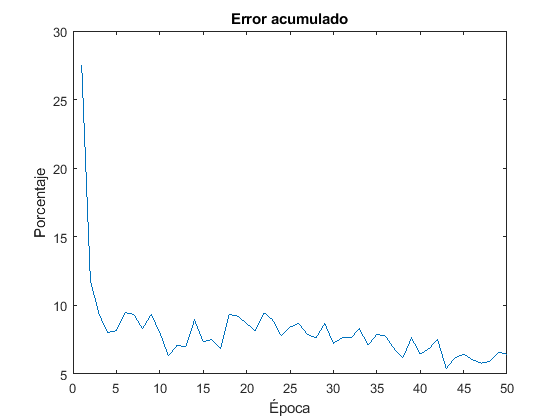

            name = strcat("./training/", categorias(i), num2str(j), ".jpg");

            p = double(reshape(imread(name), [entrada, 1]));
            salida = p;
            salidas{1} = salida;

Propagamos hacia adelante

            for k = 1:num_capas
                    salida = capas{k}(pesos{k} * salida + bias{k});
                    salidas{k+1} = salida;
            end

Calculamos el error, antes redondeamos la salida, el cell de etiquetas indica cuál es el valor esperado de cada categoría usando el índice del mismo.

            salida(salida>0.5) = 1;
            salida(salida<=0.5) = 0;
            salidas{k+1} = salida;
            
            error = etiquetas{i} - salida;
            error_acumulado = error_acumulado + error' * error;

En caso de que el error sea distinto de 0, entonces tenemos que hacer Backpropagation

            if ~isequal(error, zeros(neuronas(end), 1))
                % Backpropagation
                for k = num_capas:-1:1

Los hiperparámetros son:

                    if k == num_capas

	Tasa de aprendizaje alfa: 0.170000

                        sensitividades{k} = -2 * eye(neuronas(k)) * derivadas{k}(salidas{k+1}) * error;

	Número de capas: 2

                    else

	Número de neuronas: 2  1

                        sensitividades{k} = eye(neuronas(k)) * derivadas{k}(salidas{k+1})...
                                        * pesos{k+1}' * sensitividades{k+1};


Los resultados del modelo son:

                    end

	Error acumulado: 10.000000 %

                end

	Casos totales: 30

	Casos fallidos: 3

                for k = num_capas:-1:1
                    pesos{k} = pesos{k} - alfa * sensitividades{k} * salidas{k}';
                    bias{k} = bias{k} - alfa * sensitividades{k};
                end
            end
            

Cerramos los for anteriores

        end % For que recorre categorías
    end % For que recorre imágenes

Ahora procedemos a calcular el error acumulado, el error acumulado se ha sumado durante toda la época y sabemos que puede tener un valor máximo del tamaño del vector de salida * 190 (que son el número de imágenes) * 2 (que son el número de categorías). Así que, de ahí sale la siguiente fórmula para su procentaje

    error_acumulado = 100 * error_acumulado / (length(salida) * num_imagenes * length(categorias));
    errores(epoca) = error_acumulado;
end % While de épocas

Por último vamos a hacer una gráfica de cómo ha cambiado el error con respecto al tiempo (en unidades de épocas)

plot(1:epoca, errores);
title("Error acumulado");
ylabel("Porcentaje");
xlabel("Época");

## Validación

Para la validación, lo que hacemos es usar un conjunto de imágenes diferentes y hacer propagación hacia adelante, luego tomamos datos a partir de eso y mostramos parámetros de cómo se comporta nuestra red. Inicializamos variables

error_acumulado = 0;
num_imagenes = 15;
fallidos = 0;

Esto fragmento contiene la misma propagación hacia adelante, podría hacerse función, pero se dejó así para ilustrar directamente su funcionamiento

El modelo dice que es: cloudy
./testing/cloudy93.jpg


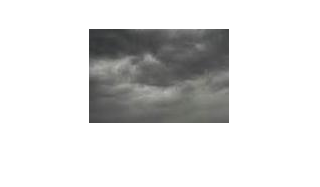

for j = 1:num_imagenes % Recorre las imágenes
    for i = 1:length(categorias) % Recorre las categorías
        % Seleccionamos la imagen y la hacemos vector
        name = strcat("./validation/", categorias(i), num2str(j), ".jpg");
        p = double(reshape(imread(name), [entrada, 1]));
        salida = p;
        
        % Propagación hacia adelante

        for k = 1:num_capas
                salida = capas{k}(pesos{k} * salida + bias{k});
        end
        
        % Calculamos el error
        salida(salida>0.5) = 1;
        salida(salida<=0.5) = 0;
        
        error = etiquetas{i} - salida;
        error_acumulado = error_acumulado + error' * error;
        
        if ~isequal(error, zeros(neuronas(end), 1))
            fallidos = fallidos + 1;
        end
    end
end

Calulamos el error acumulado, esta vez es solo una vez

error_acumulado = 100 * error_acumulado / (length(salida) * num_imagenes * length(categorias));

Imprimimos los parámetros de la red

fprintf("Los hiperparámetros son:");
fprintf("\tTasa de aprendizaje alfa: %f", alfa);
fprintf("\tNúmero de capas: %d", num_capas);
fprintf("\tNúmero de neuronas: " + num2str(neuronas));

fprintf("\nLos resultados del modelo son:");
fprintf("\tError acumulado: %f %%", error_acumulado);
fprintf("\tCasos totales: %d", num_imagenes * length(categorias));
fprintf("\tCasos fallidos: %d", fallidos);

## Prueba

Aquí solo tomamos una imagen al azar y vemos su resultado de la red y mostramos la imagen,

maximos = [95, 152];
categoria = randi(length(categorias), [1, 1]);
j = randi(maximos(categoria), [1, 1]);
name = strcat("./testing/", categorias(categoria), num2str(j), ".jpg");
[p, m] = imread(name);
salida = double(reshape(p, [entrada, 1]));


Propagación hacia adelante

for k = 1:num_capas
    salida = capas{k}(pesos{k} * salida + bias{k});
end

Redondeamos la salida

salida(salida > 0.5) = 1;
salida(salida <= 0.5) = 0;

Revisamos cuál ha sido la salida y lo imprimimos

for i = 1:length(categorias)
    if isequal(etiquetas{i}, salida)
        res = categorias(i);
        break;
    end
end

fprintf("El modelo dice que es: %s\n", res); disp(name); imshow(p, m);